# LINEALIZACIÓN Y REPRESENTACIÓN EN ESPACIO DE ESTADOS DE UN MODELO DE SUSPENSIÓN ACTIVA

## **INTRODUCCIÓN**

La suspensión de un vehículo forma un sistema muy imperativo para un automóvil, y que ayuda a proporcionar sustento al motor, la carrocería del vehículo, los pasajeros y por otro lado se mitiga los temblores que surgen debido a la irregularidad de la superficie de la carretera. Un sistema de suspensión es una combinación de resortes, amortiguadores y articulaciones que es responsable de la conexión entre la carrocería de un vehículo y sus ruedas. Los muelles y amortiguadores que conectan el eje al chasis de la carrocería juegan un papel importante a la hora de minimizar las vibraciones.

## **ANALISIS Y DINAMICA DEL SISTEMA.**

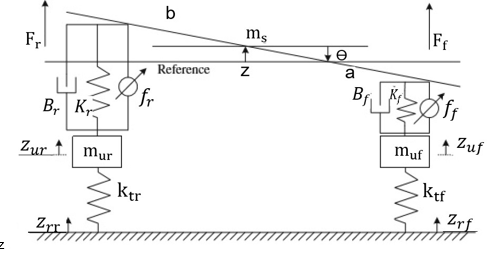

Figura 1: Diagrama de cuerpo libre de la mitad de un auto

Figura 1 ilustra el modelo de medio auto. Una sola masa suspendida (chasis) está conectada a dos masas no suspendidas (ambas ruedas) en cada esquina. El movimiento vertical y de cabeceo es aplicable para la masa suspendida, mientras que solo el movimiento vertical con chasis es aplicable para ambas masas de ruedas. Las suspensiones modeladas entre chasis y ambas ruedas son resortes y amortiguadores convencionales mientras que los neumáticos están diseñados como resortes convencionales sin humedad.

Al aplicar la ley de Newton de movimiento, se hallan las ecuaciones de estados; las siguientes ecuaciones de estado son derivadas.

## **RAZONES DE CAMBIO DE LOS ESTADOS**

**Ecuación 1**


$${\dot{\mathit{\mathbf{x}}} }_1 =x_2$$
 

**Ecuación 2**


$${\dot{\mathit{\mathbf{x}}} }_2 =\frac{1}{m_s }{\left[-{\left(B_f +B_r \right)}x_2 +{\left(aB_f -bB_r \right)}x_4 \cos x_3 -K_f x_5 +B_f x_6 -K_r x_7 +B_r x_8 +{\left(f_f +f_r \right)}+K_{tf} z_{rf} +K_{tr} x_{7rr} \right]}$$


**Ecuación 3**


$${\dot{\mathit{\mathbf{x}}} }_3 =x_4$$
 

**Ecuación 4**


$${\dot{\mathit{\mathbf{x}}} }_4 =\frac{1}{J_y }{\left[{\left(aB_f -bB_r \right)}x_2 \cos x_3 -\left(a^2 B_f +b^2 Br\right)x_4 \cos^2 x_3 +{aK_f x}_5 \cos x_3 -{aB_f x}_6 \cos x_3 -{bK_r x}_7 \cos x_3 +{bB_r x}_8 \cos x_3 +\left(af_f +bf_r \right)\cos x_3 +K_{tf} z_{rf} +K_{tr} z_{rr} \right]}$$


**Ecuación 5**


$${\dot{\mathit{\mathbf{x}}} }_5 =x_2 -aX_4 \cos x_3 -x_6$$
 

**Ecuación 6**


$${\dot{\mathit{\mathbf{x}}} }_6 =\frac{1}{m_{uf} }{\left[-K_{tf} x_1 +B_f x_2 +aK_{tf} \sin x_3 -aB_f x_4 \cos x_3 +{\left(K_f +K_{tf} \right)}x_5 -B_f x_6 +K_{tf} z_{rf} -f_f \right]}$$


**Ecuación 7**


$${\dot{\mathit{\mathbf{x}}} }_7 =x_2 +bx_4 \cos x_3 -x_8$$
 

**Ecuación 8**


$${\dot{\mathit{\mathbf{x}}} }_8 =\frac{1}{m_{ur} }{\left[-K_{tr} x_1 +B_r x_2 -bK_{tr} \sin x_3 -bB_r x_4 \cos x_3 +{\left(K_r +K_{tr} \right)}x_7 -B_r x_8 +K_{tr} z_{rr} -f_f \right]}$$


## **ESTADOS.**

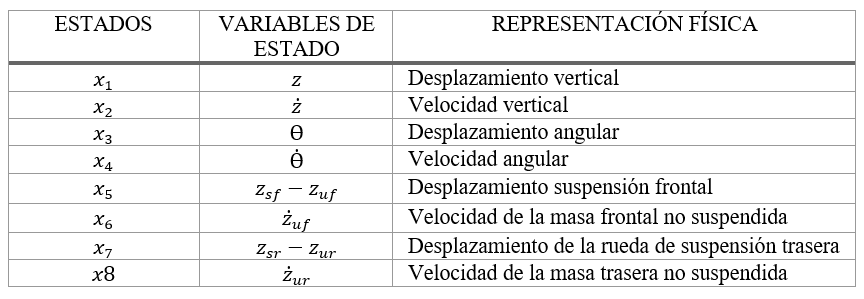

Tabla 1 Estados

## **PARAMETROS DEL SISTEMA.**

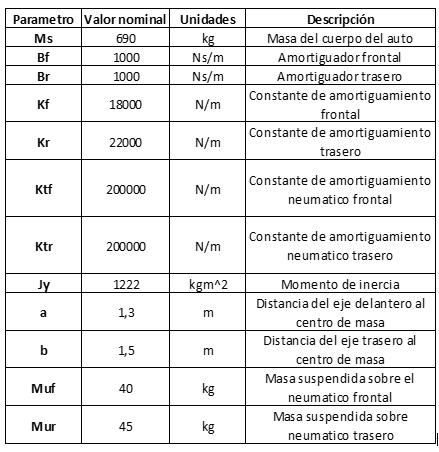

Tabla 2 Constantes del sistema

## **PUNTOS DE EQUILIBRIO**

Para obtener la matricez A,B,C y D, del espacio de estados, se hace uso del la función  "jacobian(F,X)", la cual deriva parcialmente una función con respecto a una variable. 

syms x1 x2 x3 x4 x5 x6 x7 x8 Ms Bf Br Kf Kr Ff Fr Ktf Ktr Zrf Zrr Jy a b Muf Mur
%f son las razones de cambio de los estados

f1 = x2;
f2 = (-(Bf+Br)*x2 + (a*Bf - b*Br)*x4*cos(x3) - Kf*x5 + Bf*x6 - Kr*x7 + Br*x8 + (Ff+Fr) + Ktf*Zrf +Ktr*Zrr)/Ms;
f3 = x4;
f4 = ((a*Bf - b*Br)*x2*cos(x3) - (a^2*Bf + b^2*Br)*x4*cos(x3)^2 + a*Kf*x5*cos(x3) - a*Bf*x6*cos(x3) - b*Kr*x7*cos(x3) + b*Br*x8*cos(x3) +(a*Ff+b*Fr)*cos(x3) + Ktf*Zrf + Ktr*Zrr)/Jy;
f5 = x2 - a*x4*cos(x3) - x6;
f6 = (-Ktf*x1 + Bf*x2 + a*Ktf*sin(x3) - a*Bf*x4*cos(x3) + (Kf + Ktf)*x5 -Bf*x6 + Ktf*Zrf - Ff)/Muf;
f7 = x2 + b*x4*cos(x3) - x8;
f8 = (-Ktr*x1 + Br*x2 -b*Ktr*sin(x3) - b*Br*x4*cos(x3) + (Kr + Ktr)*x7 - Br*x8 + Ktr*Zrr -Fr)/Mur;

F = [f1; f2; f3; f4; f5; f6; f7; f8];


X = [x1; x2; x3; x4; x5; x6; x7; x8];
u = [Ff; Fr; Zrf ;Zrr];  %Zrf y Zrr son perturbaciones
Y = [x1; x3];
A = simplify(jacobian(F,X))

B = jacobian(F,u)

$$B = \left(\begin{array}{cccc} 0 & 0 & 0 & 0\\ \frac{1}{\mathrm{Ms}} & \frac{1}{\mathrm{Ms}} & \frac{\mathrm{Ktf}}{\mathrm{Ms}} & \frac{\mathrm{Ktr}}{\mathrm{Ms}}\\ 0 & 0 & 0 & 0\\ \frac{a\,\cos\left(x_{3}\right)}{\mathrm{Jy}} & \frac{b\,\cos\left(x_{3}\right)}{\mathrm{Jy}} & \frac{\mathrm{Ktf}}{\mathrm{Jy}} & \frac{\mathrm{Ktr}}{\mathrm{Jy}}\\ 0 & 0 & 0 & 0\\ -\frac{1}{\mathrm{Muf}} & 0 & \frac{\mathrm{Ktf}}{\mathrm{Muf}} & 0\\ 0 & 0 & 0 & 0\\ 0 & -\frac{1}{\mathrm{Mur}} & 0 & \frac{\mathrm{Ktr}}{\mathrm{Mur}} \end{array}\right)$$

C = jacobian(Y,X)

$$C = \left(\begin{array}{cccccccc} 1 & 0 & 0 & 0 & 0 & 0 & 0 & 0\\ 0 & 0 & 1 & 0 & 0 & 0 & 0 & 0 \end{array}\right)$$

D = jacobian(Y,u)

$$D = \left(\begin{array}{cccc} 0 & 0 & 0 & 0\\ 0 & 0 & 0 & 0 \end{array}\right)$$

Pero en este sistema se presenta un mayor número de variables que de ecuaciones; para poder linealizar es necesario parametrizar los puntos de equilibrio alrededor de 4 variables. Para esto se procede a trabajar con las ecuaciones diferenciales del sistema, donde las razones de cambio de las variables de estado se igualan a cero.

De las ecuaciones **1,3,5,7** se tiene los siguientes resultados para **x2,x4,x6** y **x8.**


$$\textrm{x2}=0\;\;\;\;\;\;\textrm{x4}=0\;\;\;\;\;\;\;\textrm{x6}=0\;\;\;\;\;\;\;\;\textrm{x8}=0$$


De las ecuaciones **2,4,6** y **8** se obtiene las siguientes ecuaciones, donde se va asumir como constantes los términos de **x1,x3,Zrf** y **Zrr**, para obtener un sistema de ecuaciones de **4x4**. El resultado del sistema de ecuaciones da como resultado **x5,x7** y las dos entradas **Ff y Fr.**

**Ecuación 9**


$$\frac{-\textrm{Ktf}*\textrm{Zrf}-\textrm{Ktr}*\textrm{Zrr}}{\textrm{Ms}}=\frac{-\textrm{Kf}*\textrm{x5}}{\textrm{Ms}}-\frac{\textrm{Kr}*\textrm{x7}}{\textrm{Ms}}+\frac{\textrm{Ff}}{\textrm{Ms}}+\frac{\textrm{Fr}}{\textrm{Ms}}$$
 

**Ecuación 10**


$$\frac{-\textrm{Ktf}*\textrm{Zrf}-\textrm{Ktr}*\textrm{Zrr}}{\textrm{Jy}}=\frac{a*\textrm{Kf}*\cos \left(\textrm{x3}\right)*\textrm{x5}}{\textrm{Jy}}-\frac{b*\textrm{Kr}*\cos \left(\textrm{x3}\right)*\textrm{x7}}{\textrm{Jy}}+\frac{a*\cos \left(\textrm{x3}\right)\textrm{Ff}}{\textrm{Jy}}+\frac{b*\cos \left(\textrm{x3}\right)\textrm{Fr}}{\textrm{Jy}}$$


**Ecuación 11**


$$\frac{-\textrm{Ktf}*\textrm{x1}-a*\textrm{Ktf}*\sin \left(\textrm{x3}\right)-\textrm{Ktf}*\textrm{Zrf}}{\textrm{Muf}}=\frac{\left(\textrm{Kf}+\textrm{Ktf}\right)*\textrm{x5}}{\textrm{Muf}}-\frac{\textrm{Ff}}{\textrm{Muf}}$$


**Ecuación 12**


$$\frac{-\textrm{Ktr}*\textrm{x1}+b*\textrm{Ktr}*\sin \left(\textrm{x3}\right)-\textrm{Ktr}*\textrm{Zrr}}{\textrm{Mur}}=-\frac{\left(\textrm{Kr}+\textrm{Ktr}\right)*\textrm{x7}}{\textrm{Mur}}-\frac{\textrm{Fr}}{\textrm{Mur}}$$


Para resolver el sistema de ecuciones se uso el metodo de matriz inversa

P= [-Kf/Ms -Kr/Ms 1/Ms 1/Ms;
    (a*Kf*cos(x3))/Jy (-b*Kr*cos(x3))/Jy (a*cos(x3))/Jy (b*cos(x3))/Jy;
    (Kf+Ktf)/Muf 0 -1/Muf 0;
    0 (Kr+Ktr)/Mur 0 -1/Mur];

Q = [(-Ktf*Zrf-Ktr*Zrr)/Ms;
    (-Ktf*Zrf-Ktr*Zrr)/Jy;
    (Ktf*x1-a*Ktf*sin(x3) - Ktf*Zrf)/Muf;
    (Ktr*x1+b*Ktr*sin(x3) - Ktr*Zrr)/Mur];

R = simplify(inv(P)*Q)

$$R = \begin{array}{l} \left(\begin{array}{c} \frac{b\,\sigma_{1}}{\sigma_{4}}-\frac{\sigma_{1}}{\cos\left(x_{3}\right)\,\sigma_{4}}-\frac{\mathrm{Ktf}\,\left(a-b\right)\,\sigma_{2}}{\sigma_{4}}\\ x_{1}-\mathrm{Zrr}+b\,\sin\left(x_{3}\right)-\frac{a\,\left(2\,\mathrm{Kf}+\mathrm{Ktf}\right)\,\sigma_{1}}{\mathrm{Ktr}\,\sigma_{4}}+\frac{\mathrm{Ktf}\,\sigma_{1}}{\sigma_{3}}-\frac{2\,\mathrm{Kf}\,\mathrm{Ktf}\,a\,\sigma_{2}}{\mathrm{Ktr}\,\sigma_{4}}\\ \frac{b\,\sigma_{1}\,\left(\mathrm{Kf}+\mathrm{Ktf}\right)}{\sigma_{4}}-\frac{\sigma_{1}\,\left(\mathrm{Kf}+\mathrm{Ktf}\right)}{\cos\left(x_{3}\right)\,\sigma_{4}}+\frac{\mathrm{Kf}\,\mathrm{Ktf}\,\left(a+b\right)\,\sigma_{2}}{\sigma_{4}}\\ \mathrm{Kr}\,\left(x_{1}-\mathrm{Zrr}+b\,\sin\left(x_{3}\right)\right)-\frac{a\,\left(2\,\mathrm{Kf}+\mathrm{Ktf}\right)\,\sigma_{1}\,\left(\mathrm{Kr}+\mathrm{Ktr}\right)}{\mathrm{Ktr}\,\sigma_{4}}+\frac{\mathrm{Ktf}\,\sigma_{1}\,\left(\mathrm{Kr}+\mathrm{Ktr}\right)}{\sigma_{3}}-\frac{2\,\mathrm{Kf}\,\mathrm{Ktf}\,a\,\left(\mathrm{Kr}+\mathrm{Ktr}\right)\,\sigma_{2}}{\mathrm{Ktr}\,\sigma_{4}} \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=\mathrm{Ktf}\,\mathrm{Zrf}+\mathrm{Ktr}\,\mathrm{Zrr}\\ \sigma_{2}=\mathrm{Zrf}-x_{1}+a\,\sin\left(x_{3}\right)\\ \sigma_{3}=\mathrm{Ktr}\,\cos\left(x_{3}\right)\,\sigma_{4}\\ \sigma_{4}=2\,\mathrm{Kf}\,a+\mathrm{Ktf}\,a-\mathrm{Ktf}\,b \end{array}$$

(inv(P)*Q)

$$ans = \begin{array}{l} \left(\begin{array}{c} \frac{b\,\sigma_{3}}{\sigma_{2}}-\frac{\left(a-b\right)\,\sigma_{4}}{\sigma_{2}}-\frac{\sigma_{3}}{\cos\left(x_{3}\right)\,\sigma_{2}}\\ \frac{\sigma_{5}}{\mathrm{Ktr}}-\frac{\sigma_{3}\,\sigma_{6}}{\sigma_{1}}+\frac{\mathrm{Ktf}\,\sigma_{3}}{\cos\left(x_{3}\right)\,\sigma_{1}}-\frac{2\,\mathrm{Kf}\,a\,\sigma_{4}}{\sigma_{1}}\\ \frac{\sigma_{3}\,\left(\mathrm{Kf}\,b+\mathrm{Ktf}\,b\right)}{\sigma_{2}}+\frac{\left(\mathrm{Kf}\,a+\mathrm{Kf}\,b\right)\,\sigma_{4}}{\sigma_{2}}-\frac{\sigma_{3}\,\left(\mathrm{Kf}+\mathrm{Ktf}\right)}{\cos\left(x_{3}\right)\,\sigma_{2}}\\ \frac{\mathrm{Kr}\,\sigma_{5}}{\mathrm{Ktr}}-\frac{2\,\left(\mathrm{Kf}\,\mathrm{Kr}\,a+\mathrm{Kf}\,\mathrm{Ktr}\,a\right)\,\sigma_{4}}{\sigma_{1}}+\frac{\left(\mathrm{Kr}\,\mathrm{Ktf}+\mathrm{Ktf}\,\mathrm{Ktr}\right)\,\sigma_{3}}{\cos\left(x_{3}\right)\,\sigma_{1}}-\frac{\sigma_{3}\,\sigma_{6}\,\left(\mathrm{Kr}+\mathrm{Ktr}\right)}{\sigma_{1}} \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=2\,\mathrm{Kf}\,\mathrm{Ktr}\,a+\mathrm{Ktf}\,\mathrm{Ktr}\,a-\mathrm{Ktf}\,\mathrm{Ktr}\,b\\ \sigma_{2}=2\,\mathrm{Kf}\,a+\mathrm{Ktf}\,a-\mathrm{Ktf}\,b\\ \sigma_{3}=\mathrm{Ktf}\,\mathrm{Zrf}+\mathrm{Ktr}\,\mathrm{Zrr}\\ \sigma_{4}=\mathrm{Ktf}\,\mathrm{Zrf}-\mathrm{Ktf}\,x_{1}+\mathrm{Ktf}\,a\,\sin\left(x_{3}\right)\\ \sigma_{5}=\mathrm{Ktr}\,x_{1}-\mathrm{Ktr}\,\mathrm{Zrr}+\mathrm{Ktr}\,b\,\sin\left(x_{3}\right)\\ \sigma_{6}=2\,\mathrm{Kf}\,a+\mathrm{Ktf}\,a \end{array}$$

## **MODELO NUMERICO LINEAL**

Obtenidas las expresiones del punto de equilibrio, se procede a realizar el modelo de espacio número. Para esto vamos a utllizar el comando '**subs**', para poder actulizar datos de las matrices **A,B,C** y **D**.

Msn = 690; 
Bfn = 1000; 
Brn = 1000; 
Kfn = 18000; 
Krn = 22000; 
Ktfn = 200000; 
Ktrn = 200000; 
Jyn = 1222; 
an = 1.3; 
bn = 1.5; 
Mufn = 40; 
Murn = 45; 
x10n = 0.2;
x30n = 0.1;
Zrfn = 0.001;
Zrrn = 0.002;
Rpn = double(subs(R,{x1,x3,Zrf,Zrr,Ms,Bf,Br,Kf,Kr,Ktf,Ktr,Jy,a,b,Muf,Mur},{x10n,x30n,Zrfn,Zrrn,Msn,Bfn,Brn,Kfn,Krn,Ktfn,Ktrn,Jyn,an,bn,Mufn,Murn}));
x20n = 0;
x40n = 0; 
x50n = Rpn(1);
x60n = 0;
x70n = Rpn(2);
x80n = 0;
Ff0n = Rpn(3);
Fr0n = Rpn(4);

Apn = double(subs(A,{x1,x2,x3,x4,x5,x6,x7,x8,Ff,Fr,Zrf,Zrr,Ms,Bf,Br,Kf,Kr,Ktf,Ktr,Jy,a,b,Muf,Mur},{x10n,x20n,x30n,x40n,x50n,x60n,x70n,x80n,Ff0n,Fr0n,Zrfn,Zrrn,Msn,Bfn,Brn,Kfn,Krn,Ktfn,Ktrn,Jyn,an,bn,Mufn,Murn}));
Bpn = double(subs(B,{x1,x2,x3,x4,x5,x6,x7,x8,Ff,Fr,Zrf,Zrr,Ms,Bf,Br,Kf,Kr,Ktf,Ktr,Jy,a,b,Muf,Mur},{x10n,x20n,x30n,x40n,x50n,x60n,x70n,x80n,Ff0n,Fr0n,Zrfn,Zrrn,Msn,Bfn,Brn,Kfn,Krn,Ktfn,Ktrn,Jyn,an,bn,Mufn,Murn}));
Cpn = double(subs(C,{x1,x2,x3,x4,x5,x6,x7,x8,Ff,Fr,Zrf,Zrr,Ms,Bf,Br,Kf,Kr,Ktf,Ktr,Jy,a,b,Muf,Mur},{x10n,x20n,x30n,x40n,x50n,x60n,x70n,x80n,Ff0n,Fr0n,Zrfn,Zrrn,Msn,Bfn,Brn,Kfn,Krn,Ktfn,Ktrn,Jyn,an,bn,Mufn,Murn}));
Dpn = double(subs(D,{x1,x2,x3,x4,x5,x6,x7,x8,Ff,Fr,Zrf,Zrr,Ms,Bf,Br,Kf,Kr,Ktf,Ktr,Jy,a,b,Muf,Mur},{x10n,x20n,x30n,x40n,x50n,x60n,x70n,x80n,Ff0n,Fr0n,Zrfn,Zrrn,Msn,Bfn,Brn,Kfn,Krn,Ktfn,Ktrn,Jyn,an,bn,Mufn,Murn}));

sys=ss(Apn,Bpn,Cpn,Dpn)

sys =
 
  A = 
            x1       x2       x3       x4
   x1        0        1        0        0
   x2        0   -2.899        0  -0.2884
   x3        0        0        0        1
   x4        0  -0.1628  0.04926   -3.192
   x5        0        1        0   -1.294
   x6    -5000       25     6468   -32.34
   x7        0        1        0    1.493
   x8    -4444    22.22    -6633   -33.17
 
            x5       x6       x7       x8
   x1        0        0        0        0
   x2   -26.09    1.449   -31.88    1.449
   x3        0        0        0        0
   x4    19.05   -1.059   -26.87    1.221
   x5        0       -1        0        0
   x6     5450      -25        0        0
   x7        0        0        0       -1
   x8        0        0     4933   -22.22
 
  B = 
             u1        u2        u3
   x1         0         0         0
   x2  0.001449  0.001449     289.9
   x3         0         0         0
   x4  0.001059  0.001221     163.7
   x5         0         0         0
  

Para saber si el sistema es estable o no, se procede a a buscar los valores propios de la matriz **A**, matriz de estados.

eig(Apn)

ans =  -12.7167 +72.3261i
 -12.7167 -72.3261i
 -11.2436 +69.4840i
 -11.2436 -69.4840i
  -1.1701 + 6.7402i
  -1.1701 - 6.7402i
  -1.5261 + 7.8994i
  -1.5261 - 7.8994i


## **MODELO DISCRETO LINEAL**

Primer paso para transofrmar el modelo continuo a uno discreto, es buscar un tiempo de muestreo adecuado; para esto se va implementar el comando '**bodemag**', el cúal nos permitira obtener un diagrama de bode del sistema de espacio de estados.

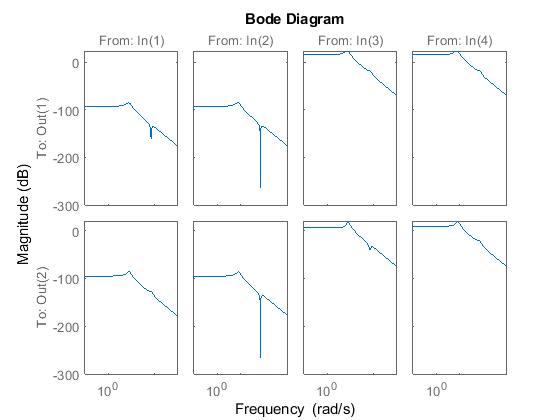

bodemag(sys)

Como el sistema presenta varios picos de resonancia, se procede a escoger una frecuencia mayor a la de estos picos, en este caso es de 137 [rad/s].  

w=137;
ws=w;
Tm=2*pi/w

Tm = 0.0459

Usando el comando '**c2d**' discretizamos el sistema de espacio de estados.

sysd = c2d(sys,Tm)

sysd =
 
  A = 
               x1          x2          x3
   x1      0.8711     0.04287    -0.01009
   x2      -5.881        0.86     -0.6369
   x3   -0.006474  -0.0002175      0.8599
   x4     -0.4265    -0.00996       -6.36
   x5       1.348     0.03321      -1.732
   x6       6.101     0.06418      -7.708
   x7       1.333     0.03206       1.913
   x8   0.0001608      0.1202       3.115
 
               x4          x5          x6
   x1   -0.001297      0.0447   0.0005844
   x2    -0.05917       2.042    0.004183
   x3      0.0418    -0.03208   -0.000411
   x4      0.8115      -1.438   -0.002207
   x5    -0.04261     -0.5044    0.002323
   x6    -0.07835       -7.08     -0.5325
   x7     0.06568    -0.01885  -0.0002526
   x8      0.2561      0.8576   -0.001216
 
               x7          x8
   x1     0.03883   0.0006658
   x2       1.953    0.006914
   x3     0.03264   0.0005583
   x4       1.638    0.005693
   x5   -0.002663  -4.156e-05
   x6    -0.04733  -0.0001261
   x7      -0.

GL = sysd.a

GL =     0.8711    0.0429   -0.0101   -0.0013    0.0447    0.0006    0.0388    0.0007
   -5.8810    0.8600   -0.6369   -0.0592    2.0420    0.0042    1.9527    0.0069
   -0.0065   -0.0002    0.8599    0.0418   -0.0321   -0.0004    0.0326    0.0006
   -0.4265   -0.0100   -6.3595    0.8115   -1.4378   -0.0022    1.6382    0.0057
    1.3479    0.0332   -1.7316   -0.0426   -0.5044    0.0023   -0.0027   -0.0000
    6.1007    0.0642   -7.7081   -0.0784   -7.0801   -0.5325   -0.0473   -0.0001
    1.3328    0.0321    1.9134    0.0657   -0.0189   -0.0003   -0.5180    0.0018
    0.0002    0.1202    3.1146    0.2561    0.8576   -0.0012   -1.4518   -0.5903


HL = sysd.b

HL =     0.0000    0.0000    0.3543    0.3523
    0.0000    0.0000   15.1344   15.1715
    0.0000    0.0000    0.1145    0.2147
    0.0001    0.0000    4.7232    9.2595
    0.0000   -0.0000   -1.2812    0.0581
    0.0000   -0.0000   -5.2423    0.7265
    0.0000    0.0000    0.4664   -0.8119
    0.0000    0.0000    3.4039    1.1678


Comparando el sistema continuo con el discreto, ante una entrada escalón, se obtiene la siguientes graficas.

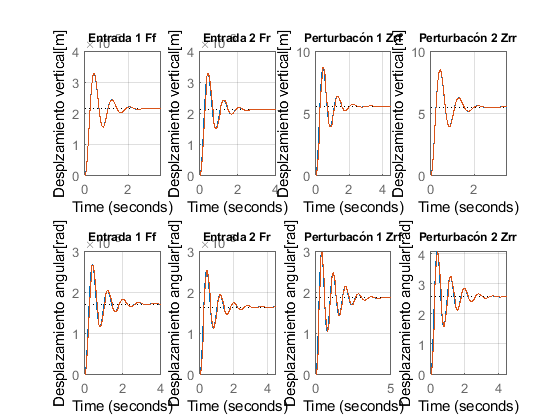

subplot(2,4,1),step(sys(1,1),sysd(1,1)),title('Entrada 1 Ff'),ylabel('Desplzamiento vertical[m]'),grid
subplot(2,4,5),step(sys(2,1),sysd(2,1)),title('Entrada 1 Ff'),ylabel('Desplazamiento angular[rad]'),grid
subplot(2,4,2),step(sys(1,2),sysd(1,2)),title('Entrada 2 Fr'),ylabel('Desplzamiento vertical[m]'),grid
subplot(2,4,6),step(sys(2,2),sysd(2,2)),title('Entrada 2 Fr'),ylabel('Desplazamiento angular[rad]'),grid
subplot(2,4,3),step(sys(1,3),sysd(1,3)),title('Perturbacón 1 Zrf'),ylabel('Desplzamiento vertical[m]'),grid
subplot(2,4,7),step(sys(2,3),sysd(2,3)),title('Perturbacón 1 Zrf'),ylabel('Desplazamiento angular[rad]'),grid
subplot(2,4,4),step(sys(1,4),sysd(1,4)),title('Perturbacón 2 Zrr'),ylabel('Desplzamiento vertical[m]'),grid
subplot(2,4,8),step(sys(2,4),sysd(2,4)),title('Perturbacón 2 Zrr'),ylabel('Desplazamiento angular[rad]'),grid